%this code take the itterated values from the tensor and restructures it
%into a struct for saving in excel
counter = 0;

%restructuring full tensor for extraction to exce file

new_test(:, :, 1) = diag(tensor_4D_full_test(:, :, 1))'.*ones(size(tensor_4D_full_test(:, :, 1)));
new_test(:, :, 2:6) = tensor_4D_full_test;
new(:, :, 1) = diag(tensor_4D_full(:, :, 1))'.*ones(size(tensor_4D_full(:, :, 1)));
new(:, :, 2:6) = tensor_4D_full;
counter = 6;
for i = 4:-1:1
    counter = counter +1;
    new_test(:, :, counter) = tensor_4D_full_test(:, :, i)';
    new(:, :, counter) = tensor_4D_full(:, :, i)';
end
new_test(:, :, 11) = diag(tensor_4D_full_test(:, :, 1)).*ones(size(tensor_4D_full_test(:, :, 1)));
new(:, :, 11) = diag(tensor_4D_full(:, :, 1)).*ones(size(tensor_4D_full(:, :, 1)));
temp = (unknown_indices == 0);

for i = 1:11
    new_test(:, :, i) = temp.*new_test(:, :, i); %removes the knwon values
    new_test(:, :, i) = triu(new_test(:, :, i)); %returns upper triangle to avoid repetion
end


counter = 0;
molar_fractions = 0:0.1:1;
Solvent_evaluated = Solvent.Name(index_smaller_subset);
for i = 1:number_rows %extracts the known values with error due to reconstruction
    for j = 1:number_columns
        for k = 1:11
   
            
            if i == j
                
            elseif new_test(i,j,k) == 0
            
            else
                counter = counter +1;
                Itterated_test.Component1(counter, 1) = Solvent_evaluated(i);
                Itterated_test.Component2(counter, 1) = Solvent_evaluated(j);
                Itterated_test.Composition1(counter, 1) = molar_fractions(k);
                Itterated_test.Speed_of_sound(counter, 1) = new_test(i,j,k);
                Itterated_test.Component1(counter, 2) = Solvent_evaluated(i);
                Itterated_test.Component2(counter, 2) = Solvent_evaluated(j);
                Itterated_test.Composition1(counter, 2) = molar_fractions(k);
                Itterated_test.Speed_of_sound(counter, 2) = new(i,j,k);

                cc(counter,1) = j; rr(counter,1) = i; %colums and row indices
            end
            
            
            
        end
    end
end

counter = 0;

%restructuring full tensor for extraction to exce file


temp = (unknown_indices+ eye(size(unknown_indices)));

for i = 1:11
    new(:, :, i) = temp.*new(:, :, i); %removes the knwon values
    new(:, :, i) = triu(new(:, :, i)); %returns upper triangle to avoid repetion
end


counter = 0;
molar_fractions = 0:0.1:1;
Solvent_evaluated = Solvent.Name(index_smaller_subset);
for i = 1:number_rows
    for j = 1:number_columns
        for k = 1:11
   
            
            if i == j
                
            elseif new(i,j,k) == 0
            
            else
                counter = counter +1;
                Itterated.Component1(counter, 1) = Solvent_evaluated(i);
                Itterated.Component2(counter, 1) = Solvent_evaluated(j);
                Itterated.Composition1(counter, 1) = molar_fractions(k);
                Itterated.Speed_of_sound(counter, 1) = new(i,j,k);
            end
            
            
            
        end
    end
end

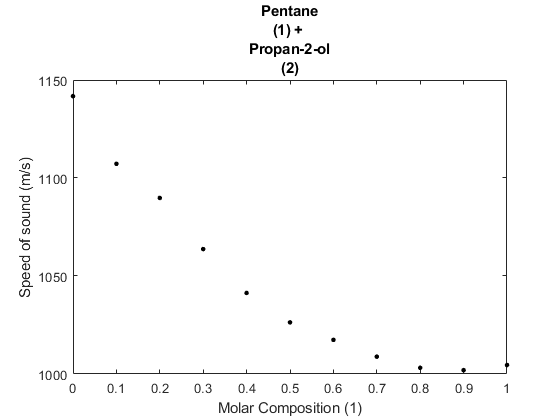

%%plotting to see how the data data varies with compostion

mutiplier = 11;
for i = 1:numel(Itterated.Component1)/mutiplier
    
    subplot(1, 1, 1);
    plot( Itterated.Composition1((i-1)*mutiplier+1:i*mutiplier), Itterated.Speed_of_sound((i-1)*mutiplier+1:i*mutiplier), ".k", "MarkerSize",10);
    xlabel("Molar Composition (1)"); ylabel("Speed of sound (m/s)");
    title([Itterated.Component1(i*mutiplier), "(1) + ", Itterated.Component2(i*mutiplier), "(2)"]);
    %pause(5)
    %below code saves image as jpeg
    f = getframe(gcf);
    filename = Itterated.Component1(i*mutiplier) + "(1) + " + Itterated.Component2(i*mutiplier) + "(2)" + ".jpg";
    %imwrite(f.cdata, fullfile(folder, filename));
end

%% plotting actual known values and that due to reconsruction
% mutiplier = 11;
% formatting = [".k", "sk"]; msize = [10, 5];
% for i = 1:numel(Itterated_test.Component1(:,1))/mutiplier
% subplot(1, 1, 1);    
%     for j = 1:2
% 
%         plot( Itterated_test.Composition1((i-1)*mutiplier+1:i*mutiplier, j), Itterated_test.Speed_of_sound((i-1)*mutiplier+1:i*mutiplier, j), formatting(j), "MarkerSize",msize(j));
%         hold on;
%         
%     end
% xlabel("Molar Composition (1)"); ylabel("Speed of sound (m/s)");
% title([Itterated_test.Component1(i*mutiplier), "(1) + ", Itterated_test.Component2(i*mutiplier), "(2)"]);
% pause(5)
% hold off
% end

% write to excel file
%T = struct2table(Itterated);
%T.Properties.VariableNames = {'Component 1', 'Component 2', 'Molar Composition 1', 'Speed of sound (m/s)'};
%writetable(T, "GR Hermanus (22796002).xlsx", "Sheet", "MCM Alkane");